#  DISEÑO FRECUENCIAL 

CONTROLADOR EN ATRASO

%ev<10%  MF>60° MG>12 dB
s=tf('s');
G=1/(s*(s+2)); %se multiplicó por un polo para tener ev
kv=1/0.1

kv = 10

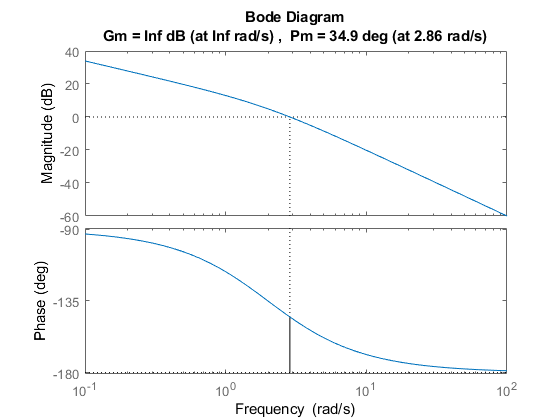

% k=0.25
k=10;
G1=k*G;
margin(G1)


 %Calcular la Fase
 
 

MF=-180+60+6

MF = -114

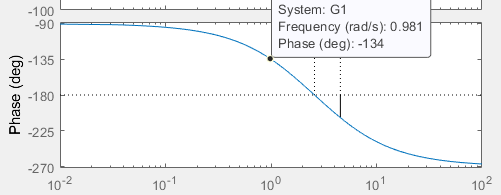

wm=0.899

wm = 0.8990

z=0.1*wm

z = 0.0899


T=1/z

T = 11.1235


%Hallar atenuación

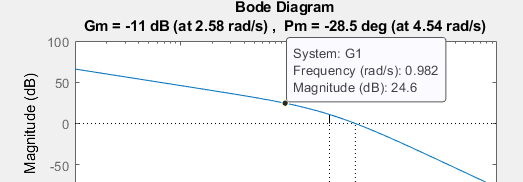

gwm=14.2

gwm = 14.2000

B=10^(-gwm/-20)

B = 5.1286


p=1/(B*T)

p = 0.0175

Kc=k/B

Kc = 1.9498

C=zpk(-z,-p,Kc)


C =
 
  1.9498 (s+0.0899)
  -----------------
     (s+0.01753)
 
Continuous-time zero/pole/gain model.




%Probar controlador, si cumple con especificaciones

L=C*G


L =
 
   1.9498 (s+0.0899)
  -------------------
  s (s+0.01753) (s+2)
 
Continuous-time zero/pole/gain model.



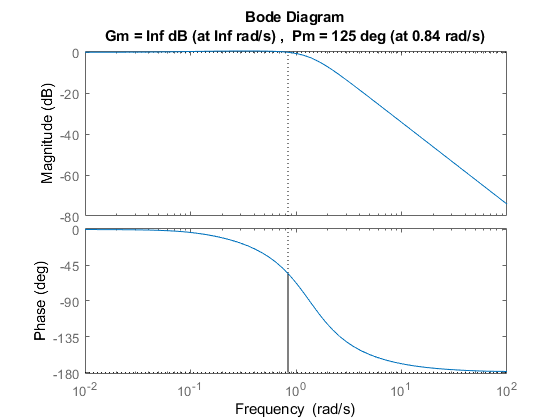


T=feedback(G,1);
Tc=feedback(G*C,1);

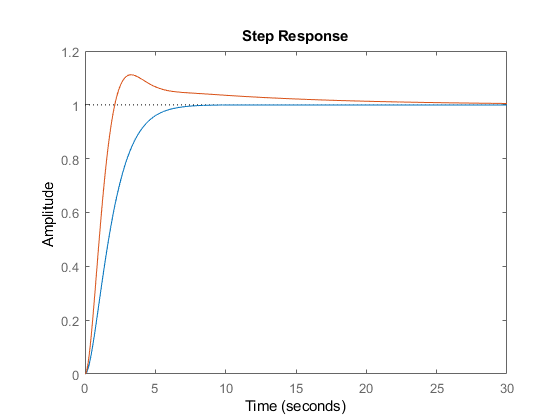

step(T,Tc)

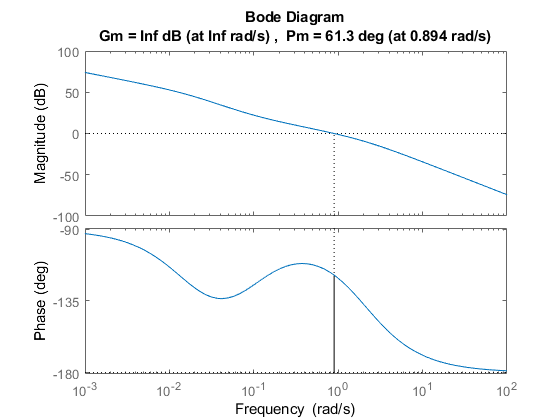

margin(L)

[MGc,MFc,Wcg,Wcf]=margin(L) 

MGc = Inf

MFc = 61.2905

Wcg = Inf

Wcf = 0.8943

margin(Tc);
